# German Stocks - Exploring II

## 1.

Load the table stored in the file `daxReturns.mat`.

load daxReturns

## 2.

Extract the DAX returns from the first column into a new table.

index = daxReturns(:,1)

index = 890×1 table
                      DAX    
                   __________
    10-Jan-2007    -0.0072545
    11-Jan-2007       0.01822
    12-Jan-2007     0.0026687
    15-Jan-2007     0.0039548
    16-Jan-2007    -0.0022188
    17-Jan-2007    -0.0022536
    18-Jan-2007    -0.0018042
    19-Jan-2007     0.0085661
    22-Jan-2007    -0.0089115
    23-Jan-2007    -0.0012539
    24-Jan-2007      0.010343
    25-Jan-2007    -0.0042753
    26-Jan-2007     -0.004361
    29-Jan-2007     0.0053174
    30-Jan-2007     0.0092081
    31-Jan-2007    0.00012963

## 3.

Extract the month information from the row names and add it as a new variable to the table. 

**Bonus** Make the month information an ordered categorical array with human-readable labels for the levels (e.g., “Jan”, “Feb”,...).

dateInfo = datetime(index.Properties.RowNames,'InputFormat','dd-MMM-yyyy');
index.Month = month(dateInfo,'shortname');
monthLabels = {'Jan','Feb','Mar','Apr','May','Jun',...
    'Jul','Aug','Sep','Oct','Nov','Dec'};
index.Month = categorical(index.Month,monthLabels,monthLabels,'Ordinal',true)

index = 890×2 table
                      DAX        Month
                   __________    _____
    10-Jan-2007    -0.0072545     Jan 
    11-Jan-2007       0.01822     Jan 
    12-Jan-2007     0.0026687     Jan 
    15-Jan-2007     0.0039548     Jan 
    16-Jan-2007    -0.0022188     Jan 
    17-Jan-2007    -0.0022536     Jan 
    18-Jan-2007    -0.0018042     Jan 
    19-Jan-2007     0.0085661     Jan 
    22-Jan-2007    -0.0089115     Jan 
    23-Jan-2007    -0.0012539     Jan 
    24-Jan-2007      0.010343     Jan 
    25-Jan-2007    -0.0042753     Jan 
    26-Jan-2007     -0.004361     Jan 
    29-Jan-2007     0.0053174     Jan 
    30-Jan-2007     0.0092081    

## 4.

Create a `boxplot` of DAX returns by month.

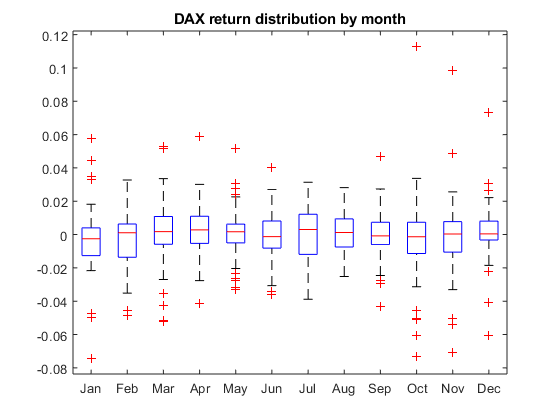

boxplot(index.DAX, index.Month);
title('DAX return distribution by month')